# Taller de Simulación Numérica

*F. Pena, P. Quintela*

## Tema 2. El método de diferencias finitas. Condiciones de contorno mixtas

Consideramos el siguiente problema de contorno $(P_R)$ con condiciones de contorno mixtas:


$$\left\{\begin{array}{ll}y''(x) = F(x,y,y'),\\-p_ay'(a)+h_ay(a)=y_a,\\p_by'(b)+h_by(b)=y_b.\end{array}$$


### Teorema de existencia y unicidad de solución

Consideramos $F(x,y,z)$ definida en $R=[a,b]\times\mathbb{R}\times\mathbb{R}$. Si se verifica que:

- $F$, $\partial_x F$, $\partial_y F$ y $\partial_{z} F$ son continuas en $R$,

- $\partial_y F > 0$ en $R$,

- existe $M$ tal que $|\partial_{z} F| < M
$en $R$,

- $p_i\geq 0,\ h_i\geq 0,\ p_i+h_i\neq 0,\ i=a,b$,

- $h_a+h_b\neq 0$.

entonces el problema [$(P_R)$](about:blank<#M_F2071021>) admite una única solución en $[a,b]$ (véase [Keller](https://projecteuclid.org/journals/bulletin-of-the-american-mathematical-society-new-series/volume-72/issue-4/Existence-theory-for-two-point-boundary-value-problems/bams/1183528184.full)).

La condición 5. implica que, en al menos en uno de los extremos, exista una condición Dirichlet o Robin. 

#### Caso lineal con condiciones Neumann o Robin

Consideramos el siguiente problema lineal $(P_{RL})$:


$$\left\{\begin{array}{ll}y''(x) = F(x,y,y') = u(x) + v(x)y+w(x)y',\\-y'(a)+h_ay(a)=y_a,\\y'(b)+h_by(b)=y_b.\end{array}$$


Si se verifica que:

- $u$, $v$, $w$ continuas en $[a,b]$,

- $v>0$ en $[a,b]$,

- existe $M = \max_{x\in[a,b]}|w(x)|$,

- $h_i\geq 0,\ i=a,b$,

- $h_a+h_b\neq 0$.

entonces el problema [$(P_{RL})$](about:blank<#M_E74087CC>) admite una única solución en $[a,b]$.

### Aproximación numérica de la solución

Tomamos una partición regular $[a,b]$ en *n* intervalos, siendo 

- el *parámetro (o paso) de discretización* $h = \frac{b-a}{n}$,

- los *puntos de la discretización *$x_i = a+i h$ para $i\in\{0,\ldots,n\}$. 

La solución aproximada en $x_i$ se denotará por $y_i$. Usaremos las siguientes fórmulas de aproximación de la derivada:


$$y'(x_i) = \frac{y(x_{i+1})-y(x_{i-1})}{2h}+O(h^2)$$



$$y''(x_i) = \frac{y(x_{i+1})-2y(x_i)+y(x_{i-1})}{h^2}+O(h^2)$$


Usándolas en [$(P_{RL})$](about:blank<#M_E74087CC>) obtenemos el problema discretizado:


$$\frac{y_{i+1}-2y_i+y_{i-1}}{h^2}=F\left(x,\  y_i,\  \frac{y_{i+1}-y_{i-1}}{2h}\right),\ i=1,\ldots, n-1,$$


#### Condición en el extremo izquierdo

Para $a=x_0$ usaremos una fórmula de Taylor:


$$y(x_1) = y(x_0) + y'(x_0)h+y''(x_0)\frac{h^2}{2}+O(h^3)$$


La solución$y$ verifica en $x_0$:


$$\left\{\begin{array}{ll}
-y'(x_0)=y_a-h_ay(x_0),\\
y''(x_0) \approx \frac{2}{h^2}\left(y(x_1)-y(x_0) - h y'(x_0)\right) = \frac{2}{h^2}\left(y(x_1)-y(x_0) +hy_a-h h_ay(x_0)\right), \\

y''(x_0) = F(x_0, y(x_0), y'(x_0)) = F(x_0, y(x_0), h_ay(x_0)-y_a).
\end{array}$$


Así, la aproximación $y_0$ se escoge cumpliendo:


$$\frac{2}{h^2}(y_1-y_0 + h y_a-h h_ay_0) = F(x_0, y_0, h_ay_0-y_a) = u_0+v_0y_0+w_0(h_ay_0-y_a),$$


donde $u_i = u(x_i),\ v_i = v(x_i),\ w_i = w(x_i)$. Agrupando términos en $y_0$, $y_1$:


$$\left(1+hh_a+\frac{h^2}{2}(v_0+h_aw_0)\right)y_0-y_1 = hy_a+\frac{h^2}{2}(-u_0+w_0y_a).$$


Condición en el extremo derecho

Para $b=x_n$ usaremos una fórmula de Taylor:


$$y(x_{n-1}) = y(x_n) - y'(x_n)h+y''(x_n)\frac{h^2}{2}+O(h^3)$$


La solución$y$ verifica en $x_n$:


$$\left\{\begin{array}{ll}
y'(x_n)=y_b-h_by(x_n),\\
y''(x_n) \approx \frac{2}{h^2}\left(y(x_{n-1})-y(x_n) + h y'(x_n)\right) = \frac{2}{h^2}\left(y(x_{n-1})-y(x_n) +hy_b-h h_by(x_n)\right), \\

y''(x_n) = F(x_n, y(x_n), y'(x_n)) = F(x_n, y(x_n), y_b-h_by(x_n)).
\end{array}$$


Así, la aproximación $y_n$ se escoge cumpliendo:


$$\frac{2}{h^2}(y_{n-1}-y_n + h y_b-h h_by_n) = F(x_n, y_n, y_b-h_by_n) = u_n+v_ny_n+w_n(y_b-h_by_n),$$


Agrupando términos en $y_{n-1}$, $y_n$:


$$-y_{n-1}+\left(1+hh_b+\frac{h^2}{2}(v_n-h_bw_n)\right)y_n = hy_b-\frac{h^2}{2}(u_n+w_ny_b).$$


#### Escritura matricial

El problema discretizado con condiciones de contorno Neumann o Robin es:


$$\left\{\begin{array}{l}d_0y_0-y_1 = hy_a+\frac{h^2}{2}(-u_0+w_0y_a),\\
a_i\,y_{i-1}+ b_i\, y_i+c_i\,y_{i+1}=-h^2u_i,\ i=1,\ldots, n-1,\\
-y_{n-1}+d_ny_n = hy_b-\frac{h^2}{2}(u_n+w_ny_b).\end{array}\right.$$


con $u_i = u(x_i),\ v_i = v(x_i),\ w_i = w(x_i)$,

 
$$


\begin{array}{rcrcl}
a_i &=& -1&-&\frac{h}{2}w_i\,, \\
d_i &=& 2 &+&h^2v_i\,, \\ 
c_i &=& -1&+&\frac{h}{2}w_i\, \ 1\leq i \leq n-1,
\end{array}$$


y los elementos diagonales extremos,

$d_0=1+hh_a+\frac{h^2}{2}(v_0+h_aw_0)$,

$d_n = 1+hh_b+\frac{h^2}{2}(v_n-h_bw_n)$.

Escrito matricialmente, es un sistema tridiagonal:


$$\left(\begin{array}{cccc}
d_0 & -1 &  &  & 0 \\
a_1 & d_1 & c_1 & &  \\
  & a_2 & d_2 & \!\!\!\!c_2 &\\
& &  \!\!\!\!\!\!\!\!\!\!\!\ddots & \!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\ddots &\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\ddots \\
  &  & a_{n-1}  & d_{n-1}  & c_{n-1}  \\
0 &  &   & -1  & d_{n} \\
\end{array} \right) \left(\begin{array}{c}y_0\\y_1\\y_2\\ \vdots\\y_{n-1}\\y_{n}\end{array}\right) = 
 \left(\begin{array}{l}
hy_a+\frac{h^2}{2}(-u_0+w_0y_a)\\
-h^2u_1\\-h^2u_2\\ \qquad \vdots\\-h^2u_{n-1}\\
hy_b-\frac{h^2}{2}(u_n+w_ny_b)\end{array}\right)$$


Si $h$ es suficientemente pequeño, la matriz sigue siendo diagonal dominante.

#### Incorporación de condiciones Dirichlet

En `dfd` se eliminaban del sistema las filas correspondientes a las incógnitas con condición Dirichlet (lo que se denomina *bloqueo por condensación*). 

Para no cambiar el tamaño del sistema lineal anterior, lo modificaremos para los extremos con condición Dirichlet. Por ejemplo, si fuese el caso de ambos extremos el sistema quedaría:


$$\left(\begin{array}{cccc}
1 &  0 &  &  & 0 \\
a_1 & d_1 & c_1 & &  \\
  & a_2 & d_2 & \!\!\!\!c_2 &\\
& &  \!\!\!\!\!\!\!\!\!\!\!\ddots & \!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\ddots &\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\!\ddots \\
  &  & a_{n-1}  & d_{n-1}  & c_{n-1}  \\
0 &  &   & 0  & 1 \\
\end{array} \right) \left(\begin{array}{c}y_0\\y_1\\y_2\\ \vdots\\y_{n-1}\\y_{n}\end{array}\right) = 
 \left(\begin{array}{l}
\ \ y_a\\
-h^2u_1\\-h^2u_2\\ \qquad \vdots\\-h^2u_{n-1}\\
\ \ y_b\end{array}\right)$$


### Implementación del método de diferencias finitas

La función [`df`](matlab:open('./df.m')) implementa el cálculo de la solución del problema discreto. Sus argumentos de entrada son:

- La estructura `F,` con tres funciones anónimas `u`, `v` y `w` que admiten como argumento un vector `x` de puntos de discretización.

- La estructura `bc,` que define las condiciones de contorno:

                  `bc.blk_a` es verdadero si hay una condición Dirichlet en $x=a$: *y*(`bc.a`) = `bc.ya`;

                  `bc.blk_a` es falso en otro caso:  -*y'*(`bc.a`) = `bc.ya` - `bc.ha` *y*(`bc.a`).

                  `bc.blk_b` es verdadero si hay una condición Dirichlet en $x=b$: *y*(`bc.b`) = `bc.yb`;

                  `bc.blk_b` es falso en otro caso:   *y'*(`bc.b`) = `bc.yb` - `bc.hb` *y*(`bc.b`).

*Esta convención puede pensarse con la regla mnemotécnica del vector normal: según el extremo, derecho o izquierdo, el vector que "sale" tiene orientación +1 o -1.*

- El número de pasos, `n`.

El resultado es:

- El vector de puntos de discretización, `x`, 

- El vector de valores de la solución aproximada en los puntos anteriores, `y`. 

**Atención:** En las explicaciones anteriores, algunos índices empiezan en cero (por ejemplo, los puntos de discretización  $\{x_i\}_{i=0}^n$). Sin embargo, en Matlab los índices deben empezar en uno.

### Ejercicio 2.1. Test académico

Considera el problema de contorno:


$$\left\{\begin{array}{ll}y''(t) = 2\text{e}^t-y,\\y(0)=2,\\y(1) = \text{e}+\cos(1),\end{array}$$


cuya solución exacta es $y(x) = \exp(x)+\cos(x)$.

- **Calcula la solución aproximada con **`df`** del problema con condiciones de contorno Dirichlet. Comprueba que se obtiene la misma solución que con **`dfd`**.**

%Solucion
F=struct('u',@(x) 2*exp(x),'v',@(x)-ones(size(x)),'w',@(x) zeros(size(x)));
bco=struct('a',0,'b',1,'ya',2,'yb',exp(1)+cos(1));

bc = struct('blk_a', true, 'a', 0, 'ya', 2,               'ha', 0, ...
            'blk_b', true, 'b', 1, 'yb', exp(1)+cos(1)  , 'hb', 0);

[~,yho]=dfd(F,bco,25);
[~,yh]=df(F,bc,25);
% Efectivamente, se trata de la misma solución.
diferencia=yh-yho

diferencia =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


- **Propón condiciones de contorno Robin para los dos extremos y calcula la solución.**

Solución:

Las condiciones a satisfacer en $a=0$ son $-y'(0)=y_a-h_ay(0),\ h_a\geq 0$. Como $y(0) = 2, y'(0)=1$, podemos tomar:

$h_a = 1,\ y_a=2h_a-1=1$.

Análogamente, para satisfacer en $b=1$ son $y'(1)=y_b-h_by(1),\ h_b\geq 0$, como $y(1) = \mathrm{e}+\cos(1)$, $y'(1)=\mathrm{e}-\sin(1)$, podemos tomar:

$h_b = 1,\ y_b=h_b(\mathrm{e}+\cos(1))+\mathrm{e}-\sin(1)= 2\mathrm{e}+\cos(1)-\sin(1)$.

%Solucion
F  = struct('u', @(x) 2*exp(x), ...
            'v', @(x) -ones(size(x)), ...
            'w', @(x) zeros(size(x)));
bc = struct('blk_a', false, 'a', 0, 'ya', 1,                      'ha', 1, ...
            'blk_b', false, 'b', 1, 'yb', 2*exp(1)+cos(1)-sin(1), 'hb', 1);
[xh, yh] = df(F, bc, 25)

xh =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000


yh =     1.9999    2.0399    2.0799    2.1201    2.1605    2.2013    2.2424    2.2839    2.3261    2.3689    2.4126    2.4571    2.5027    2.5495    2.5976    2.6471    2.6982    2.7510    2.8058    2.8627    2.9218    2.9833    3.0475    3.1146    3.1847    3.2580


- **Calcula las normas **$L^{\infty}(a,b)$ **y** $L^{2}(a,b)$** discretas del error absoluto.**

Crea dos funciones [`normaInf`](about:blank<#M_05D4D892>) y [`norma2`](about:blank<#M_8B162C27>) al final de este *script* que haga el cálculo de la norma, para poder reutilizarla en futuros apartados.

%Solucion
sol = @(x) exp(x) + cos(x);
disp(['Norma Loo discreta del error absoluto: ' num2str(normaInf(xh, yh, sol))])

Norma Loo discreta del error absoluto: 0.00055143


disp(['Norma L2  discreta del error absoluto: ' num2str(norma2(xh, yh, sol))])

Norma L2  discreta del error absoluto: 0.00036303


- **Representa grá**`fi`**camente la solución exacta, la aproximada y el error cometido en cada punto.**

Crea una función [`grafica`](about:blank<#M_628E5FE1>) al final de este *script*, para poder reutilizarla en futuros apartados.

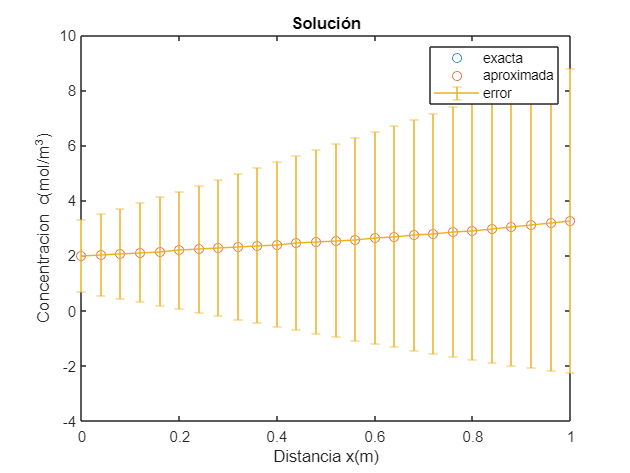

%Solucion
grafica(xh, yh, sol, 1e4,'Solución','Distancia x(m)','Concentracion c(mol/m^3)')

- **Deduce numéricamente el orden del método en las normas **$L^{\infty}(a,b)$ y $L^{2}(a,b)$** discretas.**

Crea una función [`orden`](about:blank<#M_9A2077C6>) al final de este *script*. Uno de los argumentos debe ser la función norma (`normaInf` o `norma2`) a usar.

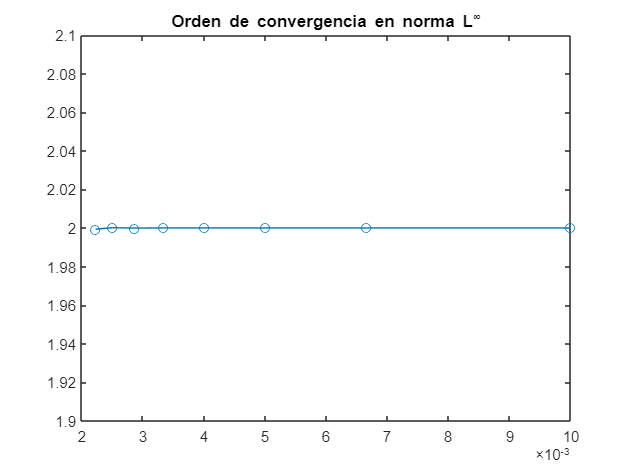

%Solucion
orden(F, bc, sol, @normaInf, 'Orden de convergencia en norma L^\infty', 1.9, 2.1)

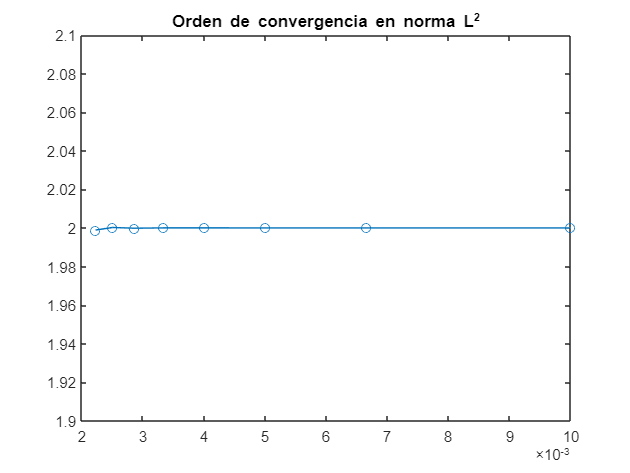

orden(F, bc, sol, @norma2, 'Orden de convergencia en norma L^2', 1.9, 2.1)

- **Impón una condición Neumann en **$x=a$** y Dirichlet en **$x=b$. **Repite todos los cálculos y gráficas anteriores.**

Solución:

Las condiciones a satisfacer en los extremos son, respectivamente: y(0)=1, y(1)=e+cos(1), así,

en x=0, y''(0)=2-y(0)=2-1=1; claramente y_a tiene que ser 0; así que -y'(0)=h_a*y(0)=-1

en x=1, se piden condiciones Dirichlet, pero el extremo ya está bloqueado, así que no hay nada que hacer.

%Solucion
F  = struct('u', @(x) 2*exp(x), ...
            'v', @(x) -ones(size(x)), ...
            'w', @(x) zeros(size(x)));
bc = struct('blk_a', false, 'a', 0, 'ya', 0,             'ha', 0.5, ...
            'blk_b', true,  'b', 1, 'yb', exp(1)+cos(1), 'hb', 0);
[xh, yh] = df(F, bc, 25)

xh =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000


yh =     2.0004    2.0404    2.0805    2.1207    2.1611    2.2018    2.2429    2.2845    2.3267    2.3695    2.4132    2.4577    2.5033    2.5501    2.5982    2.6477    2.6988    2.7516    2.8064    2.8633    2.9224    2.9839    3.0481    3.1152    3.1852    3.2586



sol = @(x) exp(x) + cos(x);
disp(['Norma Loo discreta del error absoluto: ' num2str(normaInf(xh, yh, sol))])

Norma Loo discreta del error absoluto: 0.00038462


disp(['Norma L2  discreta del error absoluto: ' num2str(norma2(xh, yh, sol))])

Norma L2  discreta del error absoluto: 0.00026725


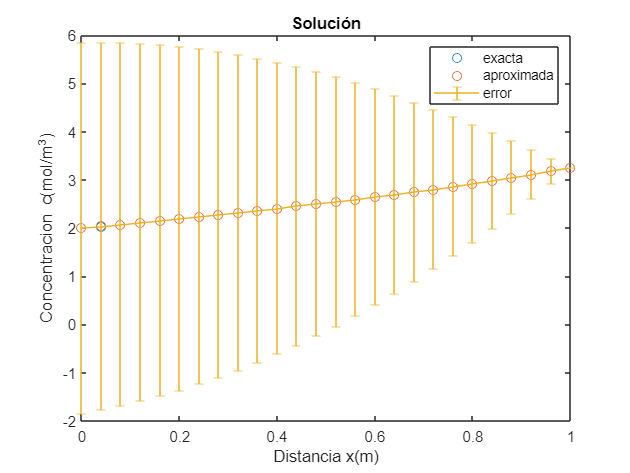

grafica(xh, yh, sol, 1e4,'Solución','Distancia x(m)','Concentracion c(mol/m^3)')

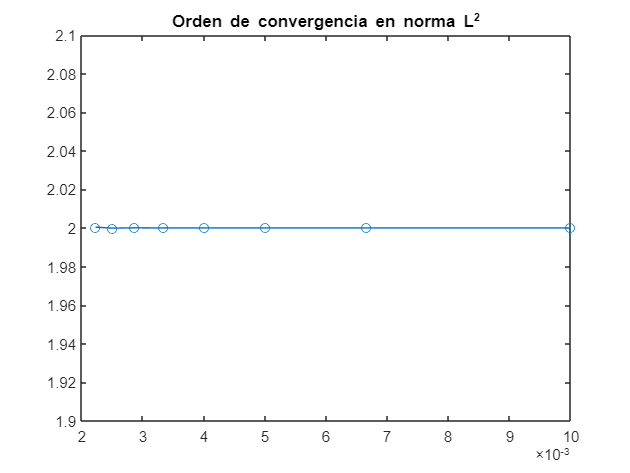

orden(F, bc, sol, @norma2, 'Orden de convergencia en norma L^2', 1.9, 2.1)

### Balance de masa de un reactor químico en estado estacionario

En la página 39 de [J. Caldwell and D.K.S Ng. Mathematical Modelling. Case Studies and Projects. Kluwer Academic Pub. 2004](http://www.math.utah.edu/~cherk/teach/5740MathModeling/12mathmodel/sources/Caldwell%20&%20Ng%202004%20Mathematical%20Modelling.Case%20Studies%20&%20Projects.pdf), se describe el balance de masa en un reactor químico en estado estacionario, con simetría cilíndrica, con un decaimiento lineal de la sustancia, y con concentración constante en cada sección. La EDO que verifica la concentración $c$ ($\text{mol}/\text{m}^3$) es:


$$Dc''-Uc'-\gamma c = 0, \ x\in[0,L]$$


siendo:

- $L$ ($\text{m}$) la longitud del tanque, 

- $D$ ($\text{m}^2/\text{h}$) el coeficiente de difusión de Fick,

- $U$($\text{m}/\text{h}$) la velocidad del agua en el tanque,

- $\gamma$ ($\text{h}^{-1}$) el coeficiente de decaimiento de la reacción.

Veamos cómo se deduce esta EDO. Consideramos un elemento de volumen entre $x$ y $x+\Delta x$, de volumen $V$ y sección transversal $A_c$. 

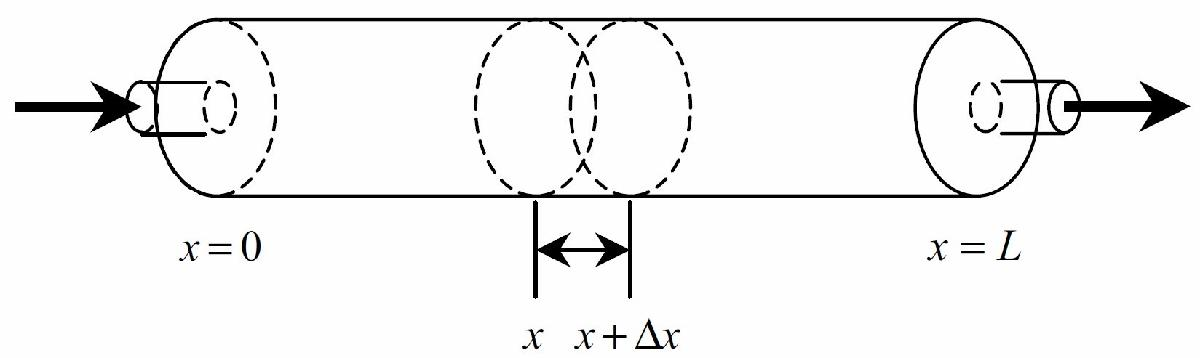

*Caldwell, Figura B1.1*

La ley de Fick indica que la densidad de corriente de partículas o *flujo difusivo* $J$ es proporcional al gradiente de la concentración en cada instante de tiempo:


$$J(x,t) =  -A_c D\, \partial_x\,c(x,t)$$


La variación de la masa por unidad de tiempo en el elemento de volumen $V\frac{\Delta c}{\Delta t}$ es debida a:

- el flujo entrante: $F\,c(x,t)$,

- el flujo saliente: $-F\, c(x+\Delta x,t)$,

- la dispersión entrante: $J(x,t) = -D\,A_c\,\partial_x\,c(x,t)$,

- la dispersión saliente: $-J(x+\Delta x,t) = D\,A_c\,\partial_x\,c(x+\Delta x,t)$,

- el decaimiento lineal: $-\gamma Vc(x,t)$,

siendo $F$ ($\text{m}^3/\text{h}$) la velocidad de flujo. En resumen,

$V\frac{\Delta c}{\Delta t} = -F\left(c(x+\Delta x,t)-c(x,t)\right) + D\,A_c\left(\partial_x\,c(x+\Delta x,t)-\partial_x\,c(x,t)\right)-\gamma V\,c(x,t)$.

Utilizamos que una función derivable $f$ cumple $f(x+\Delta x)-f(x) = f'(x)\Delta x + O(\Delta x^2)$.

$V\frac{\Delta c}{\Delta t} \approx -F\partial_x\,c(x,t)\Delta x + D\,A_c\partial^{\,2}_{xx}\,c(x,t)\Delta x-\gamma Vc(x,t)$.

Dividimos por $V$, consideramos que $V=A_c\Delta x$ y tomamos $\Delta x\to 0,\ \Delta t\to 0$:

$\partial_t\,c(x,t) = -\frac{F}{A_c}\partial_x\,c(x,t)+ D\partial^{\,2}_{xx}\,c(x,t)-\gamma c(x,t)$.

La EDO indicada al principio de este apartado se obtiene teniendo en cuenta que la velocidad del agua se puede escribir como $U=\frac{F}{A_c}$ y que en estado estacionario los campos no dependen del tiempo, además de que $\partial_t\, c(x,t) = 0$.

#### Condiciones de contorno

Se supone conocida la concentración a la entrada del tubo, $c_{in}$. El flujo a la entrada $F\,c_{in}$ es debido a:

- el flujo a la entrada del tubo: $F\,c(0
,t)$,

- la dispersión a la entrada del tubo: $J(x,t) = -D\,A_c\,\partial_x\,c(0,t)$,

es decir,

$UA_c\,c_{in} = UA_c\,c(0,t) - D\,A_c\,\partial_x\,c(0,t)$.

Dividiendo por $U\,A_c$,

$ - \partial_x\,c(0,t) + \frac{U}{D}c(0,t) = \frac{U}{D}c_{in}$.

En la salida del tubo, se supone que la dispersión ya no afecta a la tasa de salida de la concentración:

$\partial_x\,c(L,t) = 0$.

### Ejercicio 2.2. Balance de masa de un reactor en estado estacionario

Considera el problema:


$$\left\{\begin{array}{l}
c''=\frac{\gamma}{D} c+ \frac{U}{D}\,c' ,\ x\in[0,L]\\
 -c'(0,t) +\frac{U}{D}c(0,t)= \frac{U}{D}c_{in} ,\\
c'(L,t) = 0.
\end{array}$$


- **Resuelve el problema anterior** **mediante diferencias finitas.** 

Usa los siguientes datos: $L=10\, \text{m}$, $D=1\,\text{m}^2/\text{h}$, $U=1\,\text{m}/\text{h}$, $\gamma=0.2$, $c_{in}=100\,\text{mol}/\text{m}^3$, y un paso $\Delta x = 0.25\,\text{m}$. 

%Solucion
L = 10; D = 1; U = 1; gm = 0.2; cin = 100; 
F  = struct('u', @(x)   zeros(size(x)), ...
            'v', @(x) gm*ones(size(x))/D, ...
            'w', @(x)  U*ones(size(x))/D);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
            'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);
[xh, yh] = df(F, bc, round(L/0.25))

xh =          0    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000    4.2500    4.5000    4.7500    5.0000    5.2500    5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000


yh =    85.4095   81.8397   78.4192   75.1416   72.0010   68.9916   66.1081   63.3451   60.6975   58.1607   55.7299   53.4007   51.1690   49.0305   46.9816   45.0183   43.1373   41.3351   39.6084   37.9542   36.3697   34.8519   33.3985   32.0068   30.6748   29.4004   28.1819   27.0179   25.9073   24.8494   23.8443   22.8927   21.9962   21.1577   20.3820   19.6758   19.0490   18.5151   18.0933   17.8094   17.6987


- **Calcula la solución exacta.**

%Solucion
syms y(x)
Dy = diff(y,x);
sol = matlabFunction(dsolve(diff(y,x,2) - (U/D)*diff(y,x) - (gm/D)*y == 0, [...
     -Dy(bc.a)==bc.ya - bc.ha*y(bc.a), ...
      Dy(bc.b)==bc.yb - bc.hb*y(bc.b)]));

- **Representa grá**`fi`**camente la solución exacta y la aproximada.**

Compara los resultados con la Figura B1.4 de la página 50 de [Caldwell](http://www.math.utah.edu/~cherk/teach/5740MathModeling/12mathmodel/sources/Caldwell%20&%20Ng%202004%20Mathematical%20Modelling.Case%20Studies%20&%20Projects.pdf):

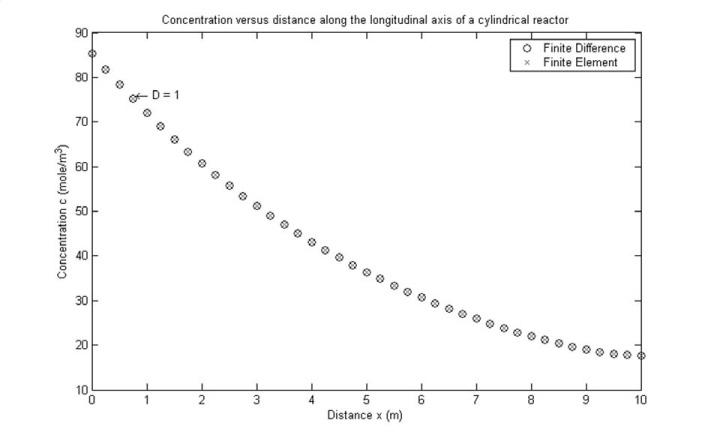

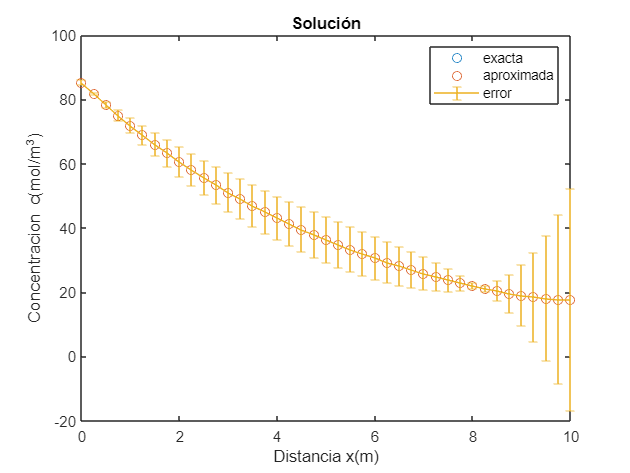

%Solucion
grafica(xh, yh, sol, 1e3,'Solución','Distancia x(m)','Concentracion c(mol/m^3)')

- **Compara las gráficas para **$D=1$ **y **$D=4$,** e interpreta el resultado.**

Compara los resultados con la Figura B1.2a de la página 46 de [Caldwell](http://www.math.utah.edu/~cherk/teach/5740MathModeling/12mathmodel/sources/Caldwell%20&%20Ng%202004%20Mathematical%20Modelling.Case%20Studies%20&%20Projects.pdf):

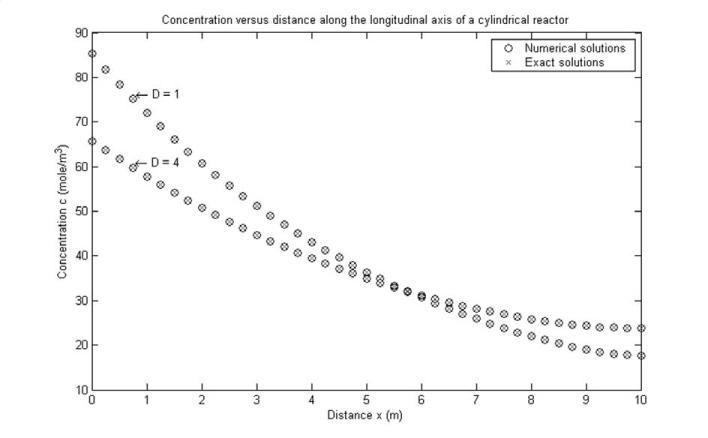

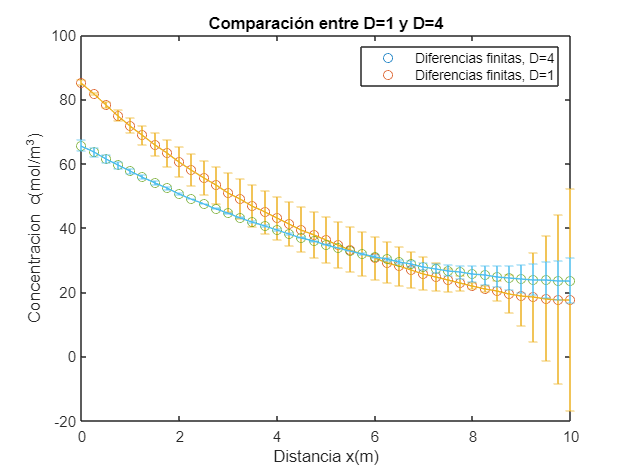

%Solucion
clf

% Es mejor idea poner solo lo que no cambie de un apartado a otro.
D = 1;
F  = struct('u', @(x)   zeros(size(x)), ...
            'v', @(x) gm*ones(size(x))/D, ...
            'w', @(x)  U*ones(size(x))/D);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
            'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);
[xh, yh] = df(F, bc, round(L/0.25));

syms y(x);
Dy = diff(y,x);
sol = matlabFunction(dsolve(D*diff(y,x,2) - U*diff(y,x) - gm*y == 0, [...
     -Dy(bc.a)==bc.ya - bc.ha*y(bc.a), ...
      Dy(bc.b)==bc.yb - bc.hb*y(bc.b)]));

grafica(xh, yh, sol, 1e3,'','Distancia x(m)','Concentracion c(mol/m^3)')

hold on

D = 4;
F  = struct('u', @(x)   zeros(size(x)), ...
            'v', @(x) gm*ones(size(x))/D, ...
            'w', @(x)  U*ones(size(x))/D);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
            'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);
[xh, yh] = df(F, bc, round(L/0.25));

syms y(x);
Dy = diff(y,x);
sol = matlabFunction(dsolve(D*diff(y,x,2) - U*diff(y,x) - gm*y == 0, [...
     -Dy(bc.a)==bc.ya - bc.ha*y(bc.a), ...
      Dy(bc.b)==bc.yb - bc.hb*y(bc.b)]));

grafica(xh, yh, sol, 1e3,'','Distancia x(m)','Concentracion c(mol/m^3)')
title('Comparación entre D=1 y D=4')
legend('Diferencias finitas, D=4','Diferencias finitas, D=1')

hold off

Interpretación:

El caso con $D=4$ tiene un mayor coeficiente de difusión. Al difundirse mejor, la concentración de las partículas tiende a igualarse a lo largo del reactor.

- **Estudia la solución para **$x=7.5\,\text{m}$.

Reproduce los resultados de la Tabla B1.1 de la página 46 de [Caldwell](http://www.math.utah.edu/~cherk/teach/5740MathModeling/12mathmodel/sources/Caldwell%20&%20Ng%202004%20Mathematical%20Modelling.Case%20Studies%20&%20Projects.pdf):

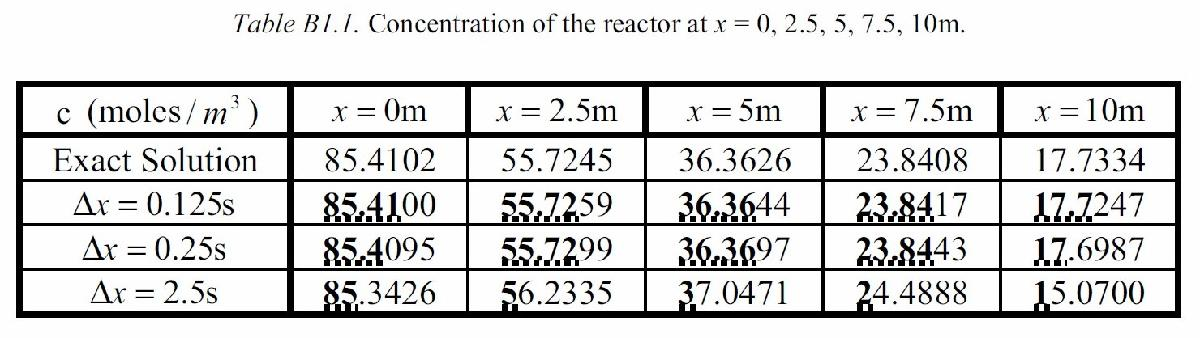

Estos datos han sido obtenidos para $D=1\,\text{m}^2/\text{h}$.

%Solucion
D = 1; pt=7.5;
F  = struct('u', @(x)   zeros(size(x)), ...
            'v', @(x) gm*ones(size(x))/D, ...
            'w', @(x)  U*ones(size(x))/D);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
            'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);


% Esto es un primer método que apliqué con otra elección para el punto
% y tratando de mezclar con un string array para que la tabla saliese tal
% cual está más arriba.

h=zeros(5,2);
h=string(h);

h(1,1)="c (moles/m^3)";
h(2,1)="Exact solution";
h(3,1)="Dx=0.125";
h(4,1)="Dx=0.25";
h(5,1)="Dx=2.5";

h(1,2)="x=7.5 m";

h(2,2)=num2str(sol(7.5));
[~, yh] = df(F, bc, round(L/0.125));
h(3,2)=num2str(yh(round((3/4)*L/0.125)+1));
[~, yh] = df(F, bc, round(L/0.25));
h(4,2)=num2str(yh(round((3/4)*L/0.25)+1));
[~, yh] = df(F, bc, round(L/2.5));
h(5,2)=num2str(yh(round((3/4)*L/2.5)+1));
h

h = 5×2 string array
    "c (moles/m^3)"     "x=7.5 m"
    "Exact solution"    "26.8853"
    "Dx=0.125"          "23.8417"
    "Dx=0.25"           "23.8443"
    "Dx=2.5"            "24.4888"


% Esto es el método de Fran (más rápido)
% for dx = [0.125 0.25 2.5]
%     [xh, yh] = df(F, bc, round(L/dx));
%     disp([' Dx = ' num2str(dx,'%4.3f') ' m: ' num2str(interp1(xh,yh,pt))])
% end

- **Compara la densidad de flujo difusivo **$J/A_c$ **para **$D=1$ **y **$D=4$.

Recuerda que la expresión del flujo difusivo es $J =  -A_c D\, \partial_x\,c$. Su densidad es $J/A_c$ (en la página 40 de [Caldwell](http://www.math.utah.edu/~cherk/teach/5740MathModeling/12mathmodel/sources/Caldwell%20&%20Ng%202004%20Mathematical%20Modelling.Case%20Studies%20&%20Projects.pdf) se denomina *flux* a esta densidad). Utiliza la siguiente fórmula para aproximar la derivada:

$f'(x) = \frac{f(x+h)-f(x-h)}{2h}+O(h^2)$.

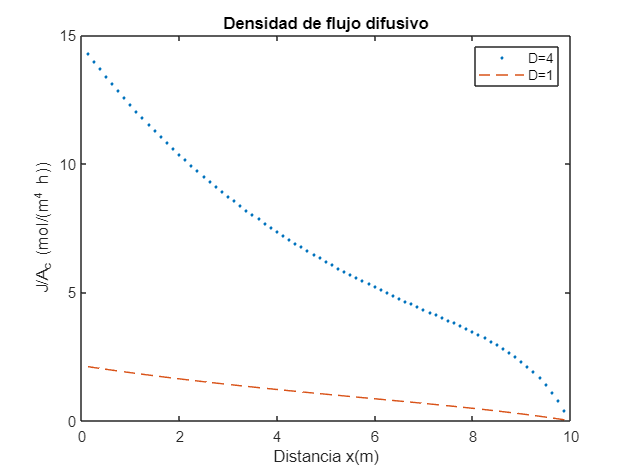

%Solucion
D = 1;
F  = struct('u', @(x)   zeros(size(x)), ...
            'v', @(x) gm*ones(size(x))/D, ...
            'w', @(x)  U*ones(size(x))/D);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
            'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);

[~, yh] = df(F, bc, round(L/0.125));
d1=(yh(3:end)-yh(1:end-2))/(2*0.125); %derivada aproximada
j1=d1.*(-D);


D = 4;
F  = struct('u', @(x)   zeros(size(x)), ...
            'v', @(x) gm*ones(size(x))/D, ...
            'w', @(x)  U*ones(size(x))/D);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
            'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);

[xh, yh] = df(F, bc, round(L/0.125));
d4=(yh(3:end)-yh(1:end-2))*(2*0.125); %derivada aproximada
j4=d4.*(-D);


plot(xh(2:end-1),j1,'.', ...
     xh(2:end-1),j4,'--')
title('Densidad de flujo difusivo')
xlabel('Distancia x(m)')
ylabel('J/A_c (mol/(m^4 h))')
legend('D=4','D=1')

Interpretación:

Un mayor coeficiente de dispersión $D$ implica una distribución mayor de la concentración (que entra por $x=0$), es decir, un mayor flujo difusivo.

- **Analiza la solución aproximada para **$D=0.01$** y distintos valores de **$h$.

Justifica por qué el cumplir la condición $h<\frac{2D}{U}$ determina la bondad de la aproximación.

Solución:

Está escrito en la otra versión, que dice algo así como: 


$$\left\{\begin{array}{l}
c''=\frac{\gamma}{D} c+ \frac{U}{D}\,c' ,\ x\in[0,L]\\
 -c'(0,t) +\frac{U}{D}c(0,t)= \frac{U}{D}c_{in} ,\\
c'(L,t) = 0.
\end{array}$$


Consideramos la discretización del modelo de reactor estacionario:


$$\frac{c_{i+1}-2c_i+c_{i-1}}{h^2} = \frac{U}{D}\frac{c_{i+1}-c_{i-1}}{2h}+\frac{\gamma}{D}c_i.$$


La discretización de la derivada segunda debe tener un valor significativo en la ecuación para todo $h>0$, **evitando un problema de perturbación singular que impediría verificar las dos condiciones de contorno de un problema de segundo orden**. Concretamente, debe cumplirse que $\frac{1}{h^2} > \frac{U}{D}\frac{1}{2h},$ es decir, $h<\frac{2D}{U}$.

Para las gráficas, tomaremos $n = [5, 50, 500]$, es decir, $h = [2,0.2,0.02]$. Para $D=1,\ U=1$ todos los $h$ verifican (o igualan) la condición. 

%Solucion
D = 0.001; U = 1;
cond=(2*D/U)

cond = 0.0020

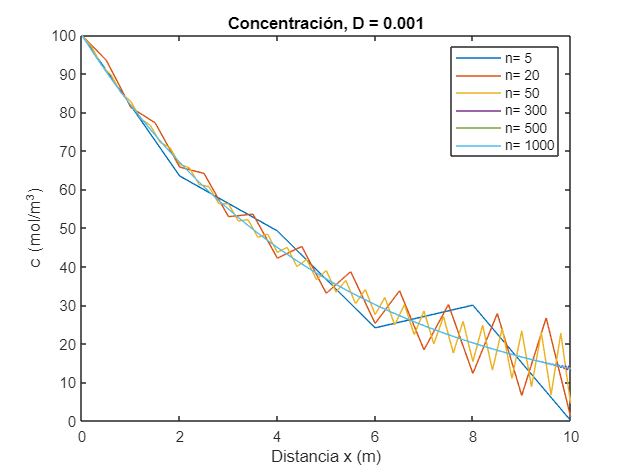

F  = struct('u', @(x)   zeros(size(x)), ...
            'v', @(x) gm*ones(size(x))/D, ...
            'w', @(x)  U*ones(size(x))/D);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
            'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);

n = [5 20 50 300 500 1000];
lgnd = strings(size(n));
for i = 1:length(n)
    [xh, yh] = df(F, bc,n(i));
    plot(xh,yh); hold on
    lgnd(i) = ['n= ' num2str(n(i))];

    h=(xh(end)-xh(1))/n(i);

    if cond>=h
        disp([' sí se cumple para n=' num2str(n(i)) ])
    end
end
legend(lgnd)
title(['Concentración, D = ' num2str(D)])
xlabel('Distancia x (m)')
ylabel('c (mol/m^3)')
hold off

Para $D=0.01$, entonces $\frac{2D}{U} = 0.02$, por lo que sólo el ultimo $h$ igualará la condición.

## **Anexo. Funciones utilizadas en esta práctica**

En Matlab, las funciones utilizadas en un *script*, van al final de éste.

function v = normaInf(xh, yh, sol)
%NORMAINF   Calculo de la norma Loo discreta del error absoluto.
ye=sol(xh);
err=abs(ye-yh);
v=norm(err,'inf');
end

function v = norma2(xh, yh, sol)
%NORMA2   Calculo de la norma L2 discreta del error absoluto.
ye=sol(xh);
err=abs(ye-yh);
v=sqrt(trapz(xh,err.^2));
end

function grafica(xh, yh, sol, escala,titulo,xlab,ylab)
%GRAFICA   Grafica de la solucion exacta, la aproximada y el error.
ye=sol(xh);
plot(xh,ye,'o',xh,yh,'o'); hold on
err=abs(ye-yh);
errorbar(xh,ye,escala*err); hold off 
legend('exacta','aproximada','error')
xlabel(xlab)
ylabel(ylab)
title(titulo)
end

function orden(F, bc, sol, norma, titulo, pmin, pmax)
%ORDEN   Orden experimental de convergencia del metodo.
n=100:50:500;
h=(bc.b-bc.a)./n;
err=zeros(size(n));
for i=1:length(n)
    [xh,yh]=df(F,bc,n(i));
    err(i)=norma(xh,yh,sol);
end
p=log(err(2:end)./err(1:end-1))./log(h(2:end)./h(1:end-1));
plot(h(1:end-1),p,'o-');
axis([h(end) h(1) pmin pmax ])
title(titulo)

end